filename = '/Users/DarellCHUA/Documents/GUI_SOLS/log_HF_Attempt.csv'

filename = '/Users/DarellCHUA/Documents/GUI_SOLS/log_HF_Attempt.csv'

data = readtable(filename);

%rawcandata = table2cell(data(1:10000,:))

rawcandata = 10000×2 cell array
    {[19-Nov-2023 09:44:49]}    {'{"BoardID":"11","SensorType":"1","Sensors":[0,42,0,47,0,103,0,7]}←↵'      }
    {[19-Nov-2023 09:45:20]}    {'{"BoardID":"11","SensorType":"1","Sensors":[0,42,0,47,0,91,0,3]}←↵'       }
    {[19-Nov-2023 09:46:25]}    {'{"BoardID":"12","SensorType":"2","Sensors":[8,117,10,164,9,84,245,210]}←↵'}
    {[19-Nov-2023 09:46:25]}    {'{"BoardID":"11","SensorType":"1","Sensors":[0,43,0,47,0,101,0,6]}←↵'      }
    {[19-Nov-2023 09:46:25]}    {'{"BoardID":"41","SensorType":"1","Sensors":[0,0,0,0,0,255,255,255]}←↵'    }
    {[19-Nov-2023 09:46:25]}    {'{"BoardID":"11","SensorType":"1","Sensors":[0,43,0,47,0,91,0,3]}←↵'       }
    {[19-Nov-2023 09:46:25]}    {'{"BoardID":"12","SensorType":"2","Sensors":[8,114,10,159,9,84,246,121]}←↵'}
    {[19-Nov-2023 09:46:25]}    {'{"BoardID":"12","SensorType":"2","Sensors":[8,114,10,159,9,84,246,121]}←↵'}
    {[19-Nov-2023 09:46:25]}    {'{"BoardID":"11","SensorType":"1","Sensors":[0,42,0,47,

rawcandata = table2cell(data(:,:))

rawcandata = (cellfun(@convertToString, rawcandata, 'UniformOutput', false))

rawcandata = 10000×2 cell array
    {["19-Nov-2023 09:44:49"]}    {1×1 struct}
    {["19-Nov-2023 09:45:20"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}
    {["19-Nov-2023 09:46:25"]}    {1×1 struct}



boardIDs = (cellfun(@(x,y)get(x,"BoardID"), rawcandata(:,2), 'UniformOutput', false))

boardIDs = 10000×1 cell array
    {'11'}
    {'11'}
    {'12'}
    {'11'}
    {'41'}
    {'11'}
    {'12'}
    {'12'}
    {'11'}
    {'11'}
    {'11'}
    {'12'}
    {'11'}
    {'11'}
    {'11'}
    {'11'}



sensorValues = (cellfun(@(x,y)get(x,"Sensors"), rawcandata(:,2), 'UniformOutput', false))

sensorValues = 10000×1 cell array
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}
    {8×1 double}


sensorValues = (cellfun(@bitto16, sensorValues, 'UniformOutput', false))

sensorValues = 10000×1 cell array
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}



datetimeoutput = string(nan(1,length(rawcandata)));
output = (nan(5,length(rawcandata)));
for i = 1:length(rawcandata)
    datetimeoutput(1,i) = string(rawcandata{i,1});
    output(1,i) = string(boardIDs{i});
    output(2:5,i) = sensorValues{i};
end

datetimeoutput

datetimeoutput = 1×10000 string array
  Columns 1 through 1310

    "19-Nov-2023 09:44:…"    "19-Nov-2023 09:45:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov-2023 09:46:…"    "19-Nov

output

output =           11          11          12          11          41          11          12          12          11          11          11          12          11          11          11          11          11          11          12          11          11          11          11          51          12          12          12          11          11          11          11          11          12          11          11          12          12          12          11          11          11          12          11          11          11          11          11          12          12          11
          42          42        2165          43           0          43        2162        2162          42          42          42        2177          42          42          42          42          42          42        2166          42          42          42          42           0        2167        2167        2167          42          42          42          42          42      

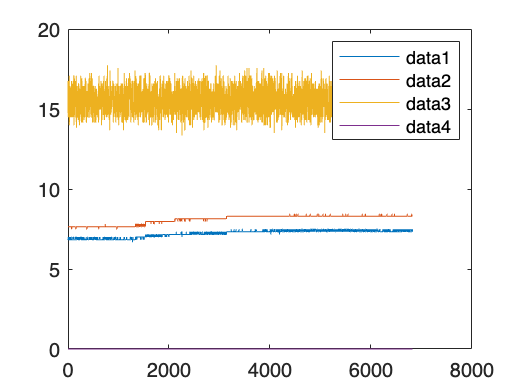


ADS1015 = 333*output(2:5,(output(1,:)==11))/2047;
plot(ADS1015')
legend()

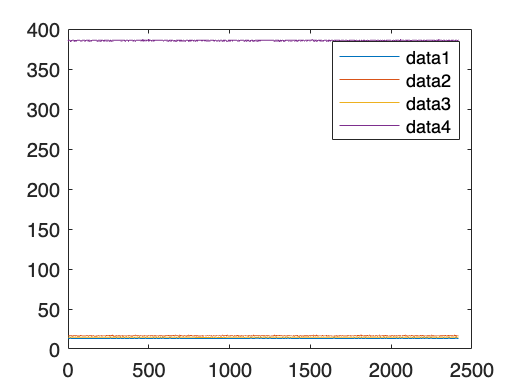


ADS1115 = 200*output(2:5,(output(1,:)==12))/32767;
plot(ADS1115')
legend()

function y = convertToString(x)
    try 
        y = jsondecode(string(x));
    catch 
        y = string(x);
        %disp(x)
    end
end

function y = get(x,str)
    try 
        y = x.(str);
    catch 
        y = nan;
        %disp(x)
    end
end

function y = bitto16(x)
    try 
        y = x([1,3,5,7])*256 + x([2,4,6,7]);
    catch 
        y = nan;
        %disp(x)
    end
end